# **Workshop** - Boat Stabilization Model Parameters

*This script defines all the parameters needed to run the workshop_boat.slx model.*

In this script we'll define numeric values for the parameters used to characterise the boat stabilization system. 

- These parameters will be used in the **Simullink** model 

Recall the main elements of the system as shown in Figure 1 below:

  **Figure 1:   The gyroscopic boat stabilizer**

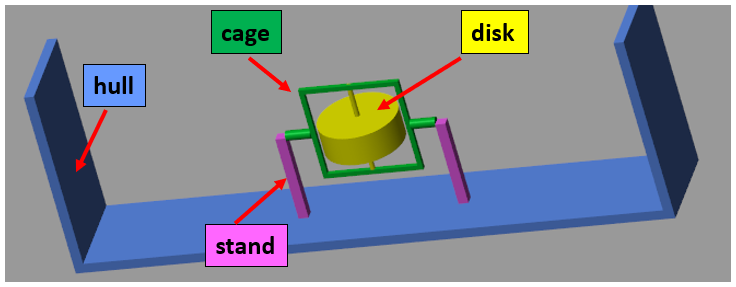 

 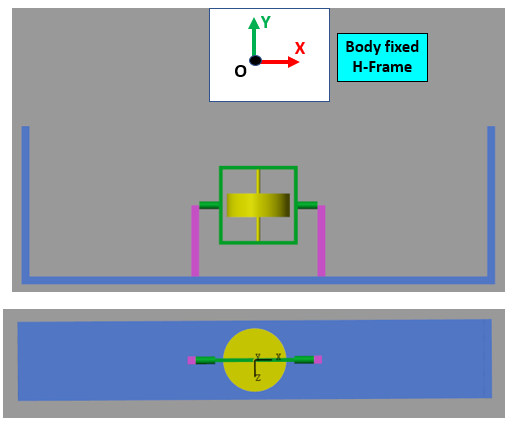

## Defining the geometry notation

We'll utilise the following length symbols

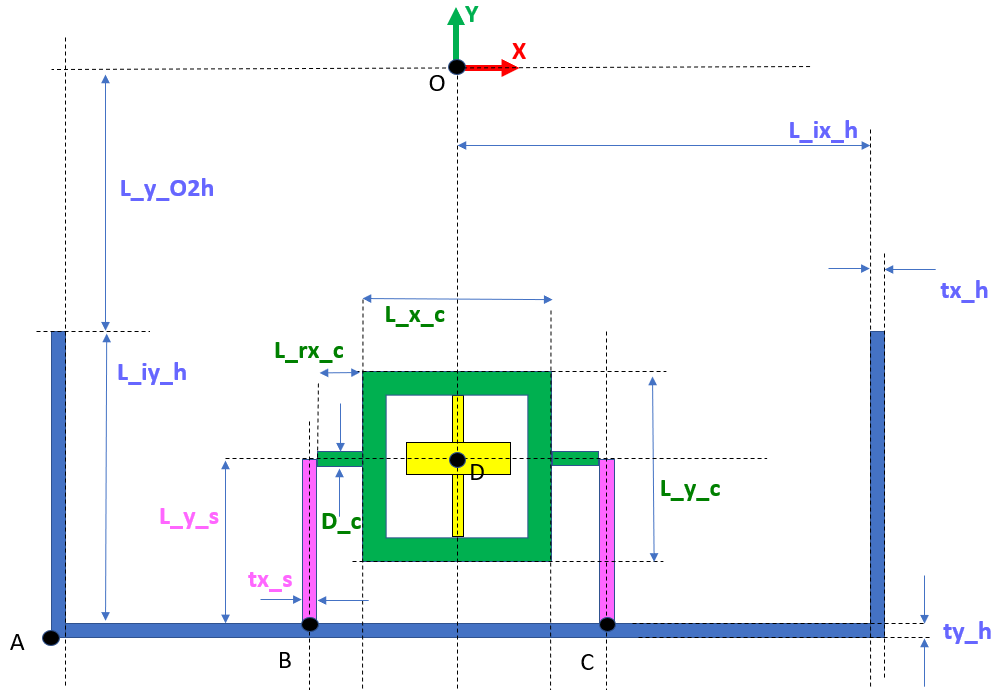

### cage params:

cage.Lx = 1;
cage.tx = 0.05;
cage.Ly = 1;
cage.ty = 0.05;
cage.tz = 0.05;
cage.D  = 0.1;
cage.L_rx = 0.25;
cage.density = 0.01; %1000;

### disk params:

disk.shaft_D = 0.05;
disk.shaft_L = cage.Ly;
disk.shaft_density = 0.1;
disk.D       = 0.8;
disk.L       = 0.3;
disk.density = 5000; %1000;

### stand params:

stand.Ly = 1.0;
stand.tx = 0.1;
stand.tz = 0.1;
stand.density = 0.1; %1000;

### hull params:

hull.tx      = 0.1;
hull.L_ix    = 2.9;
hull.ty      = 0.1;
hull.L_iy    = 1.9;
hull.tz      = 1.0; %2.0;
hull.L_y_O2h = 1.0;
hull.density = 1000;

### Points of interest:

my_points.A_rel2O = [-1*(hull.L_ix + hull.tx),  ...
                     -1*(hull.L_y_O2h + hull.L_iy + hull.ty), 0];
                 
my_points.B_rel2O = [-1*(cage.Lx/2 + cage.L_rx  + stand.tx/2), ...
                      (my_points.A_rel2O(2) + hull.ty),   0];

my_points.C_rel2O = [-1*(my_points.B_rel2O(1)), ...
                      (my_points.A_rel2O(2) + hull.ty),   0];  
                  
my_points.B_rel2A =  my_points.B_rel2O - my_points.A_rel2O;
my_points.C_rel2A =  my_points.C_rel2O - my_points.A_rel2O;

my_points.D_rel2O = [0, (my_points.B_rel2O(2) + stand.Ly), 0];

## Start a new Simscape™ Multibody™ model 

Let's open a blank Simscape Multibody model template with commonly used blocks 

open('workshop_boat_blank.slx')
model = 'workshop_boat_blank';
activeConfigObj = getActiveConfigSet(model);
tStop=45;
set_param(activeConfigObj,'StopTime','tStop');